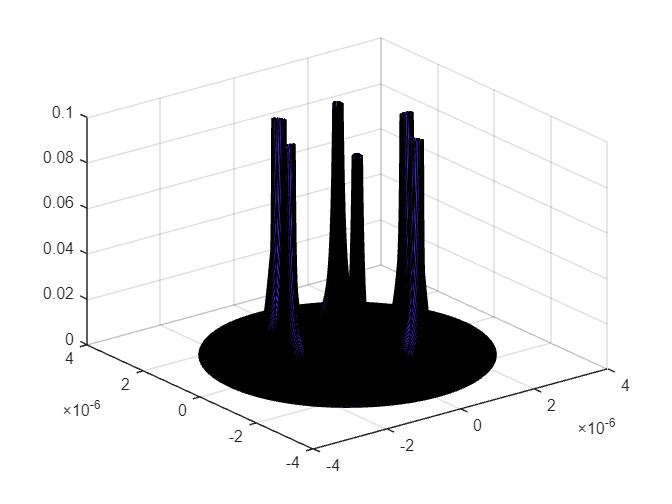


%6个粒子势能
k=9510;q=7280*1.6*10^(-19);a=1.6*10^(-6);
%fai=q*exp(-k*r)/r;


tht=0:pi/300:2*pi;
r=0:0.1*a:2*a;
[w,r]=meshgrid(tht,r);

d1=r.^2+a^2-2*a.*r.*cos(w);
fai1=q*exp(-k.*(d1))./d1;

d2=r.^2+a^2-2*a.*r.*cos(w-pi);
fai2=q*exp(-k.*(d2))./d2;

d3=r.^2+a^2-2*a.*r.*cos(w-pi/3);
fai3=q*exp(-k.*(d3))./d3;

d4=r.^2+a^2-2*a.*r.*cos(w-2*pi/3);
fai4=q*exp(-k.*(d4))./d4;

d5=r.^2+a^2-2*a.*r.*cos(w+2*pi/3);
fai5=q*exp(-k.*(d5))./d5;

d6=r.^2+a^2-2*a.*r.*cos(w+pi/3);
fai6=q*exp(-k.*(d6))./d6;



fai=fai1+fai2+fai3+fai4+fai5+fai6;

[x1,y1,z1]=pol2cart(w,r,fai);
surf(x1,y1,z1)
zlim([0,0.1])